### The Problem

The discretized system of equations can be phrased as the following: 

$\frac{d\omega }{\textrm{dt}}=-B\psi *C\omega +C\psi *B\omega +\textrm{vA}\omega$ (eqn 1)

Subjected to: 

$A\psi =\omega$ (eqn 2) 

Where $A$ is the Laplacian, and $B,C$ are $\partial x,\partial y\ldotp \;$

RHS function: 


$$\textrm{Rhs}\left(t,\omega ,A,B,C\right)$$


Omega is the ke here. 

And notice that, this is literally, a system of ODEs that can be solved directly with some native solvers in Matlab which is pretty cool!!! 

### The Key to Experiment with:

The Rhs will need to solve a system of linear equations, and that is what we are going to be experiment with. 

When solving the matrix A, on the second equation, we need to make modifictions on one entry to make it more invertible. 

Solving the eqn2: 

- Backslash 

- LU decomposition

- Biconjuegate Gradient 

- GMREM

- 2D FFT

2D FFT is the new one we are going to learn about, which is something like: 


$$\psi^{\sim } =\frac{\omega^{\sim } \;}{k_x^2 +k_t^2 }$$


Reshape $\omega$ to 2d, remap the x, y direction. 

### Discretization:

$x,y\in \left\lbrack -10,10\right\rbrack$, and $n=64$. 

n = 64; 
Params = Parameters(n, 20/n);

The params have all the discritized operators ready. 

Let's see how it works with the initial distribution. 

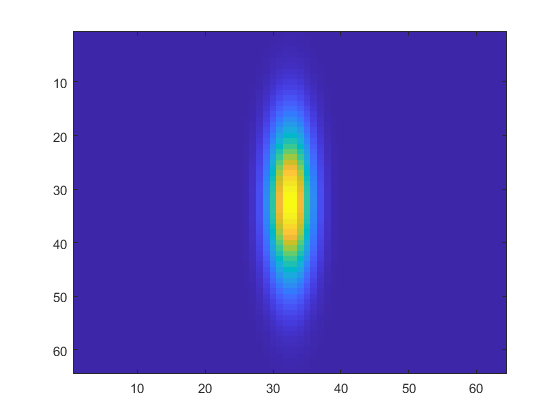

xs = linspace(-10, 10, n);
ys = linspace(-10, 10, n);
InitialDistribution = @(x, y) exp(-x.^2 - (y.^2./20));
w_vec = VectorizeInitialDistribution(xs, ys, InitialDistribution);
figure; imagesc(reshape(w_vec, n, n));

### ODEs Time Stepping

And then we are going to time step this with Rhs, and linear solve for the stream function. 

Time-Stepping details: 


$$t\in \;\left\lbrack 0:0\ldotp 5:4\right\rbrack$$


Params.SolveModes = 1; 
ODEFun = @(t, w) Rhs(w_vec, Params);
Tspan  = 0: 0.5: 4;
[Ts, Ws] = ode45(ODEFun, Tspan, w_vec); 

### Visualizing the Solutions

This is important because we can check the correctness for our solution and we can watch cool animations at the same time. 